Let's start by creating some data on which to perform inference.

rng(14);
n=500;
% rand1 = exprnd(.16,[1,floor(n/3)]);
% rand1 = rand1(rand1<=0.6);
% rand1 = rand1(rand1>0);
% rand3 = exprnd(0.12,[1,floor(n/3)])+0.5;
% rand3 = rand3(rand3<=1);
% rand3 = rand3(rand3>0.5);
lower = 0;
peak = 0.2;
upper = 1;
pd = makedist('Triangular','A',lower,'B',peak,'C',upper);
y = random(pd,1,n);

% y = ([rand1])

% y = y(y<=1);
sum(y<0)

ans = 0

sum(y>1)

ans = 0


% knots = [-0.5, 0.0, 0.1, 0.21, 0.31, 0.41, 0.51, 0.6, 0.71, 0.81, 0.91, 1, 1.5];
% d = 11;
knots = [-0.0250:0.1:1.025];
knots(end-1) = 1;
knots(2) = 0;
constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);

flag=11;
solve_this = @(a) (constraintFunc(a));
% initial = [-2, log(2), log(2.7), log(1.8), log(1.3), log(0.7), log(0.4), -2];
initial = [-2.5, log(1.6),log(2.3), log(2.4),...
    log(1.6), log(0.7), log(0.6), log(0.5), -2.5];
% initial = [-5, log(0.1), log(0.4), log(1.6), log(1.5), log(2.3), log(1.5), log(2.4), log(2.1),...
%     log(1.2), log(1.25), log(1.3), log(0.6), log(0.7),...
%     log(0.5), log(0.4), log(0.3), ...
%     -2.5];
% initial = [-2, log(1), log(2), log(1), log(0.9), log(0.7), log(0.4), -2];
initial_guess = fsolve(solve_this, initial, options)

initial_guess =    -2.4992    0.4746    0.8394    0.8821    0.4746   -0.3543   -0.5090   -0.6914   -2.4994




syms func2(x)
chosen_theta = initial_guess

chosen_theta =    -2.4992    0.4746    0.8394    0.8821    0.4746   -0.3543   -0.5090   -0.6914   -2.4994


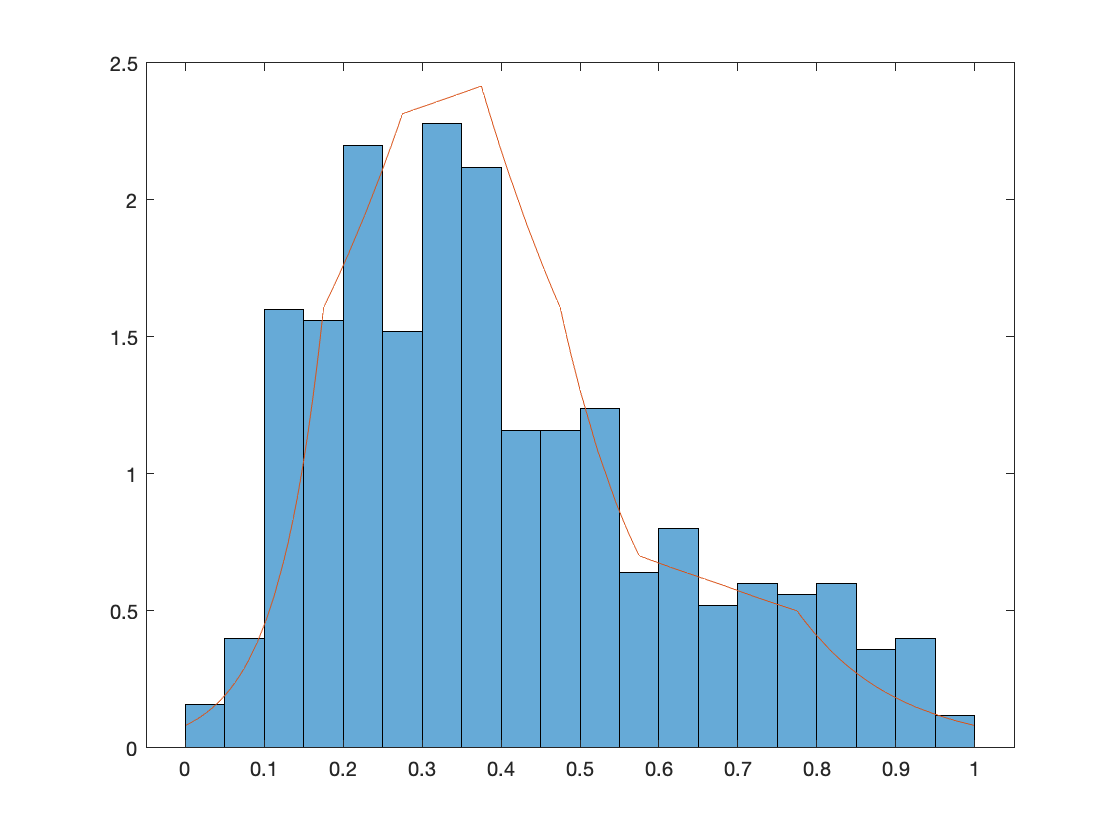

func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
%     (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
%     (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))));
histogram(y, 'Normalization','pdf','BinWidth',0.05)
hold on
fplot(func2, [0,1])
hold off

We'll select knots based on the graphic, although more principled methods exist.

% Arbitrarily choosing the starting value, with dimension parameter_dim:
data = y;
q0 = initial_guess';
nllFunc = @(x) negLog_fiducial_likelihood(knots,x,data);
conFunc = constraintFunc;

% Set parameters (that I don't quite understand)
nRuns = 1+10;
Nscale = 500;
runTime = 15; % Time per run in seconds
nTrials = 100;
doPrint = false;

samplers = struct([]);

h = 3e-5;
M = 1;
L = 10;
hmcOpts = struct('intMethod',0,'doPrint',doPrint,'printMod',10);
samplers(end+1).name = sprintf('CHMC (L = %d)',L);
samplers(end).desc = sprintf('M = %g, h = %g',M,h);
samplers(end).func = @(q,N) constrainedHMC(q,nllFunc,conFunc,M,N,L,h,hmcOpts);
samplers(end).N = ceil(Nscale./L);
samplers(end).style = 'b-';

samplerQs = cell(length(samplers),1+nTrials);
samplerStats = cell(length(samplers),1+nTrials);
samplerNLLs = cell(length(samplers),1+nTrials);
samplerTs = zeros(length(samplers),1+nTrials);
for i = 1:numel(samplers)
    fprintf('%s...',samplers(i).name);
    [q1,qs,samplerStats{i,1}] = samplers(i).func(q0,samplers(i).N);
    samplerQs{i,1} = [q0 qs q1];
    samplerTs(i,1) = samplerStats{i,1}.t/samplerStats{i,1}.N;
%     samplerNLLs{i,1} = nllFunc(samplerQs{i,1});
    
    currN = ceil(runTime./samplerTs(i,1));
    fprintf('%d samples: ',currN);
    fprintf('\n');
end

CHMC (L = 10)...

Performing a total of 50 iterations.
-----
1
0
-----
2
1
-----
3
2
-----
4
3
-----
5
3
-----
6
4
-----
7
5
-----
8
6
-----
9
7
-----
10
7
-----
11
8
-----
12
8
-----
13
8
-----
14
9
-----
15
10
-----
16
10
-----
17
10
-----
18
11
-----
19
11
-----
20
11
-----
21
11
-----
22
12
-----
23
12
-----
24
13
-----
25
14
-----
26
15
-----
27
15
-----
28
16
-----
29
17
-----
30
18
-----
31
18
-----
32
18
-----
33
19
-----
34
19
-----
35
19
-----
36
19
-----
37
19
-----
38
20
-----
39
21
-----
40
22
-----
41
23
-----
42
24
-----
43
24
-----
44
25
-----
45
26
-----
46
27
-----
47
27
-----
48
28
-----
49
29
-----
50
30


4 samples: 

mean(samplerStats{1,1}.accepted)

ans = 0.6000

Qs = samplerQs{1,1};
save("HMC_logsplineDraws_other.mat",'Qs');

Qs = load("HMC_logsplineDraws_other.mat").Qs;

samples = Qs;
mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);

chosen_theta = samples(:,26)

chosen_theta =    -2.4999
    0.4741
    0.8394
    0.8823
    0.4738
   -0.3526
   -0.5078
   -0.6912
   -2.5004



syms func1(x)
% func(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
%                     (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
%                     (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
%                     (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
%                     (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(7))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
%                     (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(8))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
%                     (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(9))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
%                     (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(10))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
%                     (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(11))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
%                     (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(12))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))) );

func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
chosen_theta = samples(:,1)

chosen_theta =    -2.4992
    0.4746
    0.8394
    0.8821
    0.4746
   -0.3543
   -0.5090
   -0.6914
   -2.4994


func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));

% fplot(y, [0,1])

% fplot(func1, [0,1])
% hold on
% fplot(func2, [0,1])
% hold off

% double(int(func1, 0, 1))
% double(int(f, 0, 1))

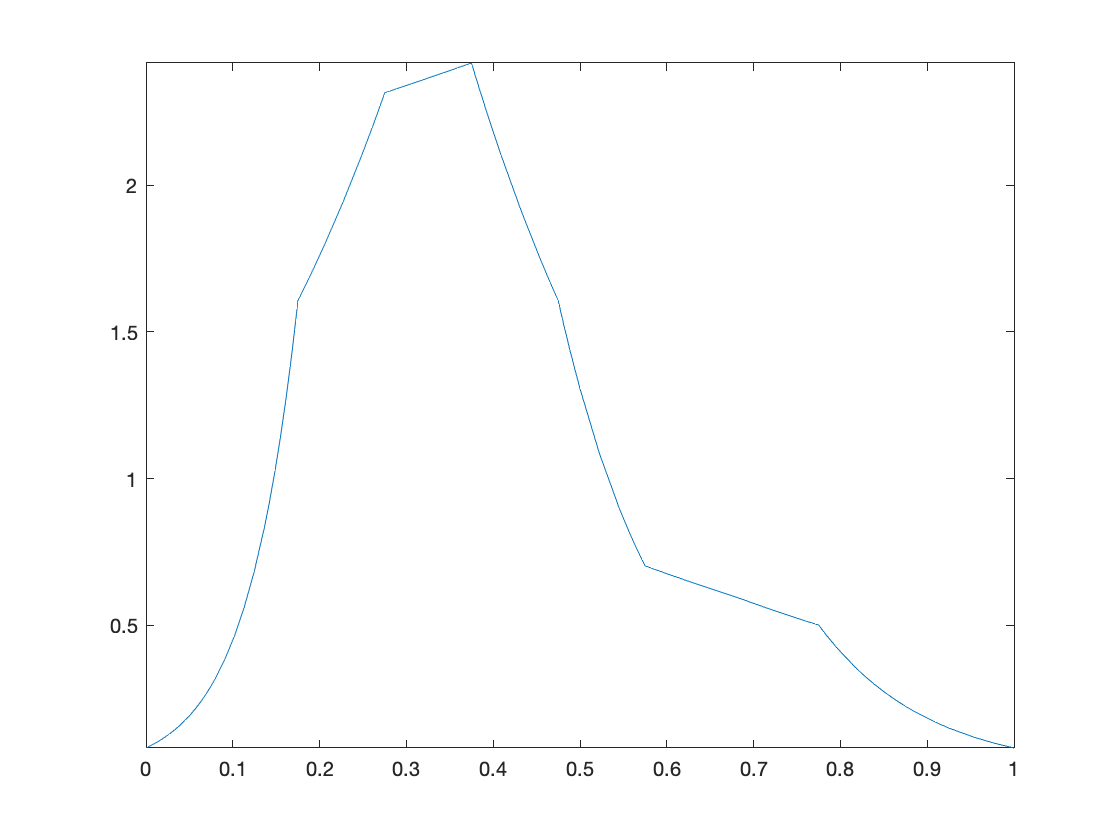

samples = matfile("HMC_logsplineDraws_other.mat");
samples = samples.Qs;
mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);

% fplot(y, [0,1])
[~,num_samples] = size(samples);
character_array = ["1"];
prev_sample = samples(:,1);
chosen_theta = initial_guess;
func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
my_plot = fplot(func1, [0,1]);

my_plot

my_plot =   FunctionLine with properties:

     Function: [1×1 symfun]
       XRange: [0 1]
        Color: [0 0.4470 0.7410]
    LineStyle: '-'
    LineWidth: 0.5000

  Show all properties




% h = figure;
% Z = peaks;
% axis tight manual
% ax = gca;
% ax.NextPlot = 'replaceChildren';
% 
% loops = length(unique(samples(1,1:1050)));
% % num = sum(accepts)
% num = 1500;
% clear M
% M(num) = struct('cdata',[],'colormap',[]);
% 
% h.Visible = 'off';
% count = 0;
% for i = 1:num_iters
%     curr_sample = samples(:,i);
%     if ~isequal(curr_sample, prev_sample)
%         count = count + 1;
% %         character_array(end+1) = int2str(i);
% %         disp(int2str(i));
% %         disp("and");
%         disp(int2str(count));
%         prev_sample = curr_sample;
% 
%         syms func2(x)
%         chosen_theta = prev_sample;
% func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
%     (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
%     (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
%     (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
%     (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
%     (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
%     (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
%     (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
%     (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
%     (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))));
%         fplot(func2, [0,1]);
%         ylim([0,4]);
%         hold on
%         histogram(y, 'Normalization','pdf','BinWidth',0.05)
%         hold off
%         drawnow
%         M(count) = getframe;
%         
%         if count == num
%             break
%         end
%     end
% end
% h.Visible = 'on';
% 
% movie(M);
% v = VideoWriter("traceplot");
% open(v)
% writeVideo(v,M)
% close(v)
% %
% % hold on
% % histogram(y, 'Normalization','pdf','BinWidth',0.01)
% % %legend(character_array)
% % hold off
% 
% % double(int(func1, 0, 1))
% % double(int(f, 0, 1))
% 
% 
% 
% all_valid = true;
% flen = length(M);
% for K = 1 : flen
%     if isempty(M(K).cdata)
%         all_valid = false;
%         str = sprintf('Empty frame occurred at frame #%d of %d\n', K, flen);
%         disp(str);
%     end
% end


mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);
chosen_theta = samples(:,min_index);


[num_rows, ~] = size(samples);
upper95s = zeros(1,num_rows);
lower5s = zeros(1,num_rows);
for i=1:num_rows
    upper95s(i) = quantile(samples(i,:),0.95);
    lower5s(i) = quantile(samples(i,:),0.05);
end

histogram(y, 'Normalization','pdf','BinWidth',0.01, 'FaceColor', 'w')
chosen_theta = upper95s;
syms func1(x)
hold on
func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
plot1 = fplot(func1, [0,1], 'LineWidth',2, 'LineStyle', "--", "Color", 'r');
% set(my_plot);

my_plot

my_plot =   handle to deleted FunctionLine


hold off


chosen_theta = lower5s;
hold on
syms func1(x)
func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
plot2 = fplot(func1, [0,1], 'LineWidth',2, "LineStyle", "-.", "Color", 'b');
% set(my_plot);
% my_plot
plot2

plot2 =   FunctionLine with properties:

     Function: [1×1 symfun]
       XRange: [0 1]
        Color: [0 0 1]
    LineStyle: '-.'
    LineWidth: 2

  Show all properties


hold off

hold on
[~,min_index] = min(mag_mean_diff);
chosen_theta = samples(:,min_index);
func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))));
plot3 = fplot(func2, [0,1], 'LineWidth', 2, 'Color', 'g');
plot3

plot3 =   FunctionLine with properties:

     Function: [1×1 symfun]
       XRange: [0 1]
        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 2

  Show all properties


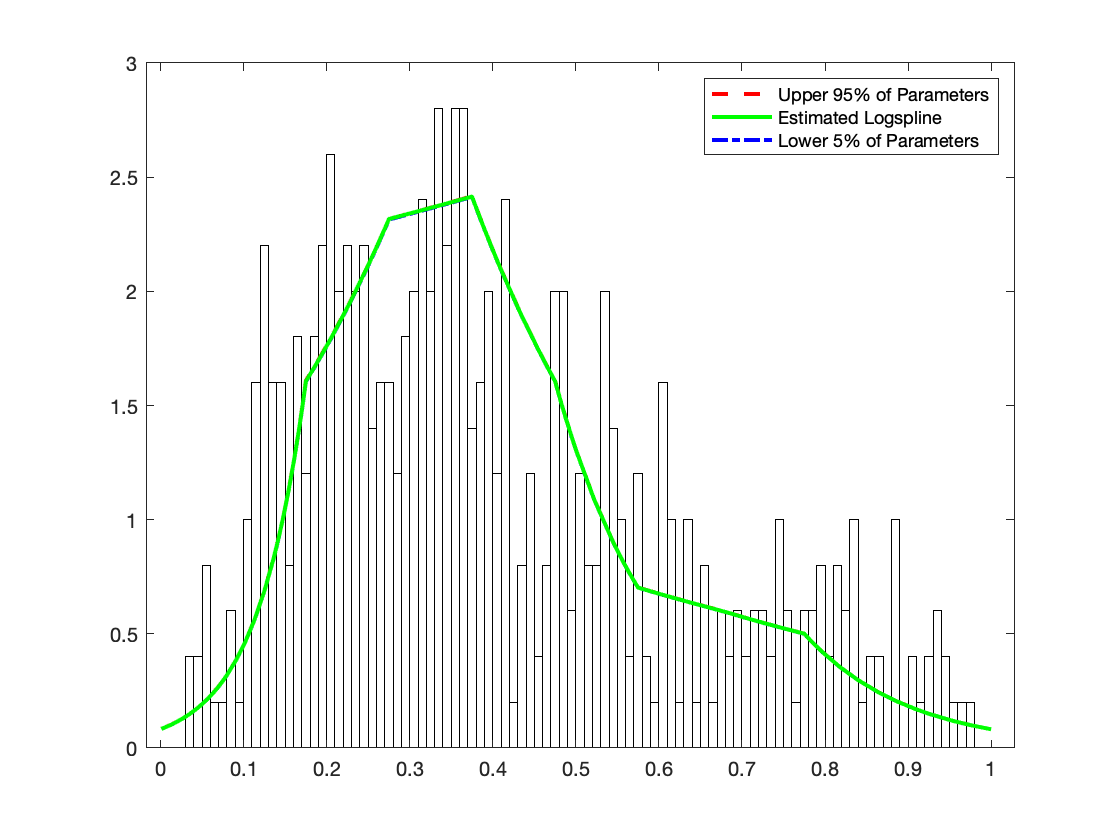

% legend(character_array)
legend([plot1, plot3, plot2],'Upper 95% of Parameters','Estimated Logspline', 'Lower 5% of Parameters')
% legend(["this", "that", "these"])
hold off

saveas(gcf,'UppersLowersMiddle.png')